# Численное моделирование

dt = 0.1

dt = 0.1000

endTime = 10

endTime = 10

t = 0:dt:endTime

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


y_0 = 25

y_0 = 25

v_0 = 30

v_0 = 30

g = 10

g = 10

y = y_0 + v_0*t - (g*t.^2) / 2

y =    25.0000   27.9500   30.8000   33.5500   36.2000   38.7500   41.2000   43.5500   45.8000   47.9500   50.0000   51.9500   53.8000   55.5500   57.2000   58.7500   60.2000   61.5500   62.8000   63.9500   65.0000   65.9500   66.8000   67.5500   68.2000   68.7500   69.2000   69.5500   69.8000   69.9500   70.0000   69.9500   69.8000   69.5500   69.2000   68.7500   68.2000   67.5500   66.8000   65.9500   65.0000   63.9500   62.8000   61.5500   60.2000   58.7500   57.2000   55.5500   53.8000   51.9500


v = v_0 - g*t

v =    30.0000   29.0000   28.0000   27.0000   26.0000   25.0000   24.0000   23.0000   22.0000   21.0000   20.0000   19.0000   18.0000   17.0000   16.0000   15.0000   14.0000   13.0000   12.0000   11.0000   10.0000    9.0000    8.0000    7.0000    6.0000    5.0000    4.0000    3.0000    2.0000    1.0000         0   -1.0000   -2.0000   -3.0000   -4.0000   -5.0000   -6.0000   -7.0000   -8.0000   -9.0000  -10.0000  -11.0000  -12.0000  -13.0000  -14.0000  -15.0000  -16.0000  -17.0000  -18.0000  -19.0000



b = [0, dt*ones(1, length(t)-1)]

b =          0    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000


v_din = v_0 - g*cumsum(b)

v_din =    30.0000   29.0000   28.0000   27.0000   26.0000   25.0000   24.0000   23.0000   22.0000   21.0000   20.0000   19.0000   18.0000   17.0000   16.0000   15.0000   14.0000   13.0000   12.0000   11.0000   10.0000    9.0000    8.0000    7.0000    6.0000    5.0000    4.0000    3.0000    2.0000    1.0000   -0.0000   -1.0000   -2.0000   -3.0000   -4.0000   -5.0000   -6.0000   -7.0000   -8.0000   -9.0000  -10.0000  -11.0000  -12.0000  -13.0000  -14.0000  -15.0000  -16.0000  -17.0000  -18.0000  -19.0000


y_din = y_0 + cumsum(v_din.*b)

y_din =    25.0000   27.9000   30.7000   33.4000   36.0000   38.5000   40.9000   43.2000   45.4000   47.5000   49.5000   51.4000   53.2000   54.9000   56.5000   58.0000   59.4000   60.7000   61.9000   63.0000   64.0000   64.9000   65.7000   66.4000   67.0000   67.5000   67.9000   68.2000   68.4000   68.5000   68.5000   68.4000   68.2000   67.9000   67.5000   67.0000   66.4000   65.7000   64.9000   64.0000   63.0000   61.9000   60.7000   59.4000   58.0000   56.5000   54.9000   53.2000   51.4000   49.5000


for i = 1 : length(y_din)-1
    if y(i) > 0 && y(i+1) < 0
        k = i
    end
end

k = 68


for i = 1 : length(y_din)-1
    if y_din(i) > 0 && y_din(i+1) < 0
        k_din = i
    end
end

k_din = 67


y_new = [y(1:k), zeros(1, length(y_din) - k)]

y_new =    25.0000   27.9500   30.8000   33.5500   36.2000   38.7500   41.2000   43.5500   45.8000   47.9500   50.0000   51.9500   53.8000   55.5500   57.2000   58.7500   60.2000   61.5500   62.8000   63.9500   65.0000   65.9500   66.8000   67.5500   68.2000   68.7500   69.2000   69.5500   69.8000   69.9500   70.0000   69.9500   69.8000   69.5500   69.2000   68.7500   68.2000   67.5500   66.8000   65.9500   65.0000   63.9500   62.8000   61.5500   60.2000   58.7500   57.2000   55.5500   53.8000   51.9500


y_new_din = [y_din(1:k_din), zeros(1, length(y_din) - k_din)]

y_new_din =    25.0000   27.9000   30.7000   33.4000   36.0000   38.5000   40.9000   43.2000   45.4000   47.5000   49.5000   51.4000   53.2000   54.9000   56.5000   58.0000   59.4000   60.7000   61.9000   63.0000   64.0000   64.9000   65.7000   66.4000   67.0000   67.5000   67.9000   68.2000   68.4000   68.5000   68.5000   68.4000   68.2000   67.9000   67.5000   67.0000   66.4000   65.7000   64.9000   64.0000   63.0000   61.9000   60.7000   59.4000   58.0000   56.5000   54.9000   53.2000   51.4000   49.5000



fg1 = figure

fg1 =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 378 560 420]
       Units: 'pixels'

  Show all properties


set(fg1, "Visible", "on")
hold all
scatter(t, y_new, 7, 'filled')
scatter(t, y_new_din, 7, 'red', 'filled')
hold off
xlabel('t, с')
ylabel('y, м')
title('Кинематическая и динамическая модель свободного падения тела - траектория')
S = sig_std_dev_to(y, y_din)

S = 2.9084

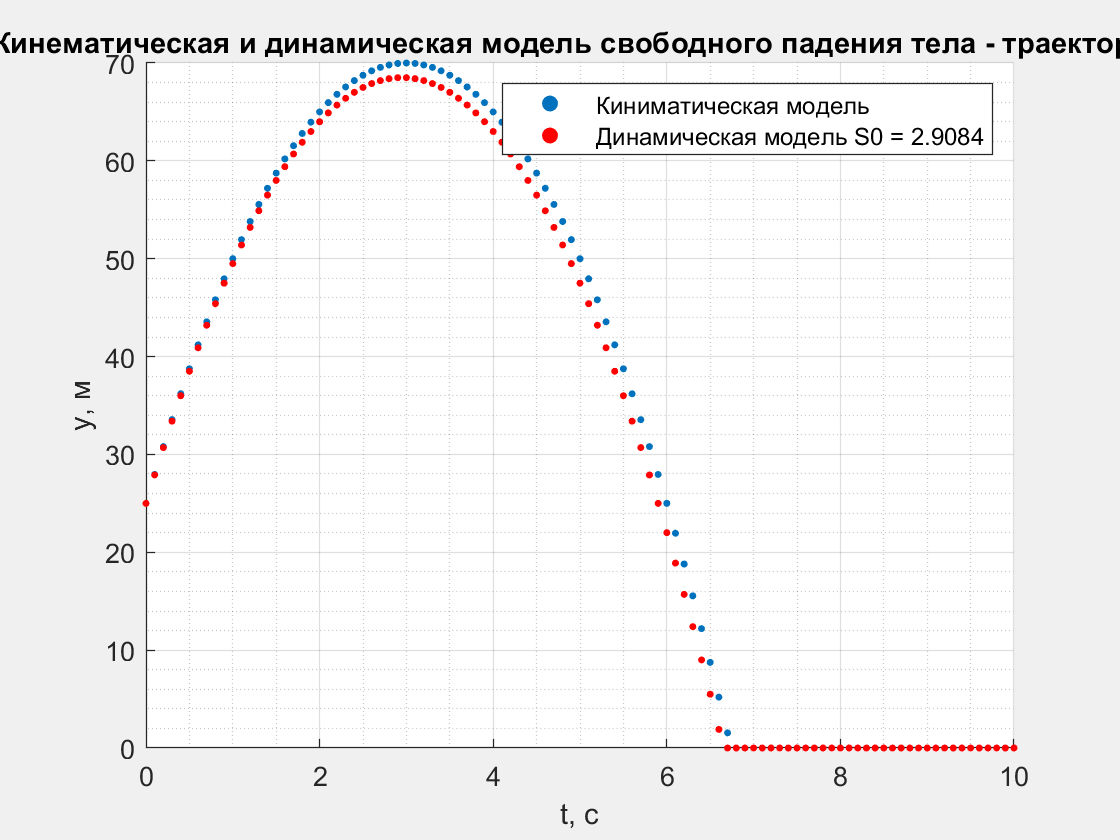

legendStr = sprintf('Динамическая модель S0 = %.4f', S);
legend('Киниматическая модель', legendStr)
grid on
grid minor


v_new = [v(1:k), zeros(1, length(v_din) - k)]

v_new =    30.0000   29.0000   28.0000   27.0000   26.0000   25.0000   24.0000   23.0000   22.0000   21.0000   20.0000   19.0000   18.0000   17.0000   16.0000   15.0000   14.0000   13.0000   12.0000   11.0000   10.0000    9.0000    8.0000    7.0000    6.0000    5.0000    4.0000    3.0000    2.0000    1.0000         0   -1.0000   -2.0000   -3.0000   -4.0000   -5.0000   -6.0000   -7.0000   -8.0000   -9.0000  -10.0000  -11.0000  -12.0000  -13.0000  -14.0000  -15.0000  -16.0000  -17.0000  -18.0000  -19.0000


v_new_din = [v_din(1:k_din), zeros(1, length(v_din) - k_din)]

v_new_din =    30.0000   29.0000   28.0000   27.0000   26.0000   25.0000   24.0000   23.0000   22.0000   21.0000   20.0000   19.0000   18.0000   17.0000   16.0000   15.0000   14.0000   13.0000   12.0000   11.0000   10.0000    9.0000    8.0000    7.0000    6.0000    5.0000    4.0000    3.0000    2.0000    1.0000   -0.0000   -1.0000   -2.0000   -3.0000   -4.0000   -5.0000   -6.0000   -7.0000   -8.0000   -9.0000  -10.0000  -11.0000  -12.0000  -13.0000  -14.0000  -15.0000  -16.0000  -17.0000  -18.0000  -19.0000



fg2 = figure

fg2 =   Figure (11) with properties:

      Number: 11
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 378 560 420]
       Units: 'pixels'

  Show all properties


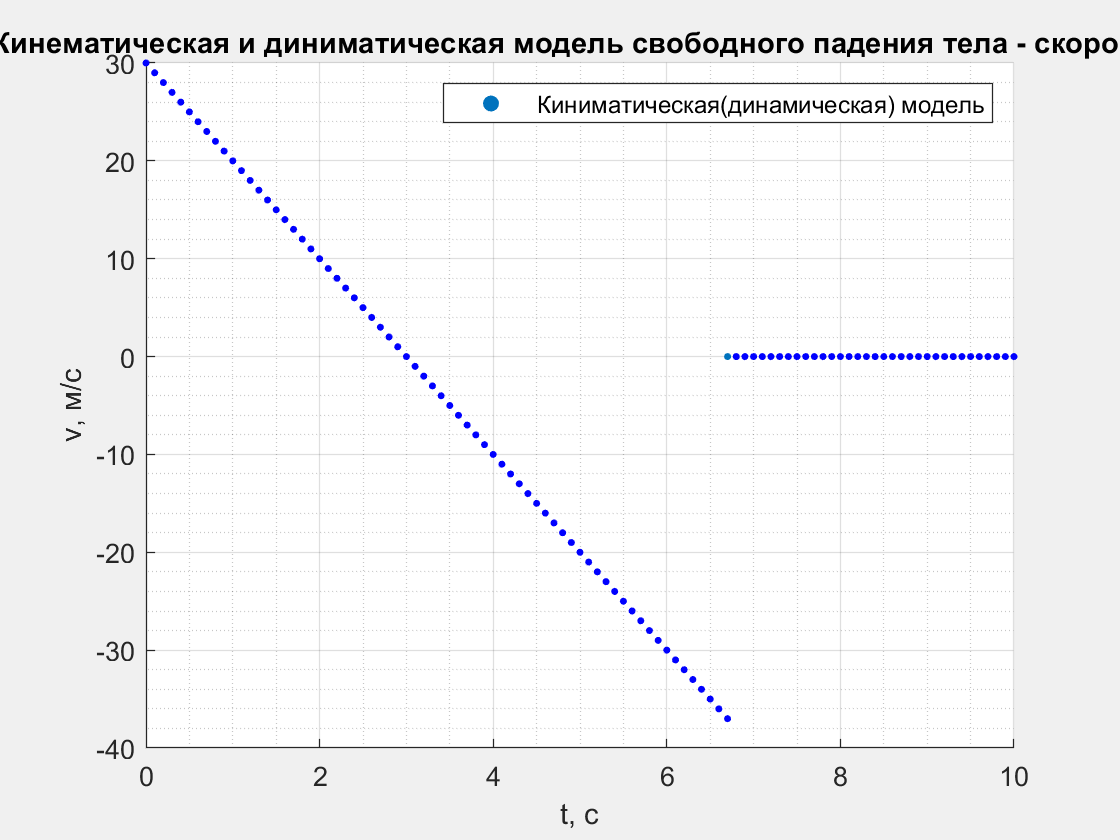

set(fg2, "Visible", "on")
hold all
scatter(t, v_new_din, 7, 'filled')
scatter(t, v_new, 7, 'blue', 'filled')
hold off
xlabel('t, с')
ylabel('v, м/c')
title('Кинематическая и диниматическая модель свободного падения тела - скорость')
legend('Киниматическая(динамическая) модель')
grid on
grid minor

step = 0.05 : 0.05 : 0.5

step =     0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000


S_full = [];
for i = step
    t_i = 0:i:endTime;
    y_i = y_0 + v_0*t_i - (g*t_i.^2) / 2;
    v_i = v_0 - g*t_i;

    b_i = [0, i*ones(1, length(t_i)-1)];
    v_din_i = v_0 - g*cumsum(b_i);
    y_din_i = y_0 + cumsum(v_din_i.*b_i);
    
    S_full = [S_full, sig_std_dev_to(y_i, y_din_i)];
end
fg3 = figure

fg3 =   Figure (12) with properties:

      Number: 12
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 378 560 420]
       Units: 'pixels'

  Show all properties


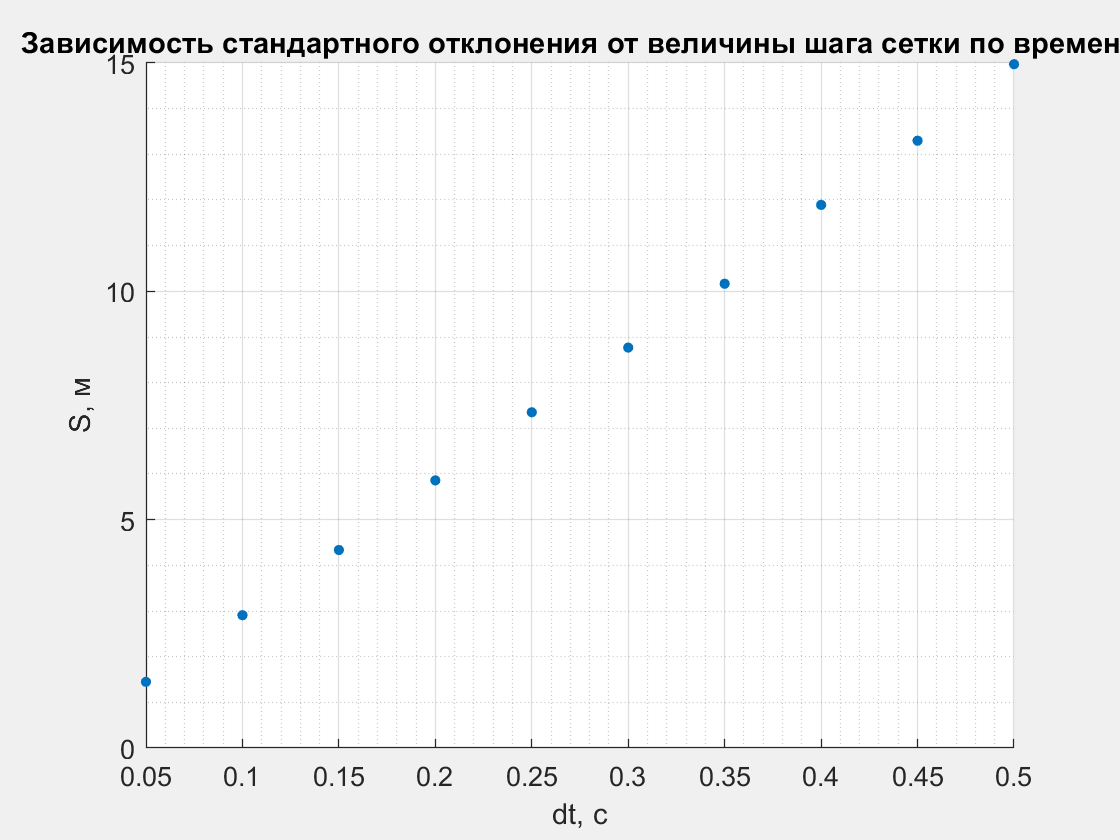

set(fg3, "Visible", "on")
scatter(step, S_full, 15, 'filled')
title("Зависимость стандартного отклонения от величины шага сетки по времени")
xlabel('dt, c')
ylabel('S, м')
grid on
grid minor

function S0 = sig_std_dev_to(x_real, x_new)
    n = length(x_real); 
    total = sqrt(sum((x_real - x_new).^2) / (n-1)); 
    S0 = total;
end